## Frequency Detection from FFT With Interpolation

A. Ehrensperger 21. 3.2023

 Initializations, Simulation Parameters

clear                  % Clear workspace

N   = 256;             % FFT length ( = simulation length), try other values 32 ...256
fs  = 8000;  T=1/fs;   % Sampling frequency, period
n   = 0:N-1;           % Sampling index
t   = n/fs;            % Sampling instance



Input Signal Parameters:

fsig    = 178.123       %  signal frequency, example, try other values

fsig = 178.1230

SNRdB   = 6            %  signal to noise ration in dB, try other values e.g 60dB, 6dB, -3dB

SNRdB = 6

phi     = 2*pi*rand     %  random initial phase

phi = 3.8563

Additive Noise Signal Parameters:  

SNR: $@\;B=\frac{f_s }{2}$,    , define Signal to Noise Ratio (SNR) in dB:

normalize for  sinwaves with ampitude =1: 0dB SNR -> $U_{\textrm{RMS}}$ = $\frac{1}{\sqrt{2}}$

SNR = 10^(-SNRdB/20)        % De-logarithmize

SNR = 0.5012

Unoise  = SNR/sqrt(2)       % Normalize RMS voltage 

Unoise = 0.3544

Ideal Complex Input Signal:

Isig=cos(2*pi*fsig*t +phi);   % In-phase signal component
Qsig=sin(2*pi*fsig*t +phi);   % Quadrature-phase signal component

Complex Additive Noise Signal: Additive White Gaussian Noise

 Inoise = Unoise * randn(1,N);    % In-phase noise component
 Qnoise = Unoise * randn(1,N);    % Quadrature-phase signal component

Combine Signal + Noise:

 I = Isig + Inoise;
 Q = Qsig + Qnoise;
 x = I +1j*Q;                % Complex combination

Plot Display Time Domain Signal (noisy and clea

clf
figure
Tdisp = 1000*T*5*ceil(fs/fsig);  % plot ca. 5 periods of input signal
maxY = 1.2* max(I);
t_ms = 1000*t;                      % t in ms

plot(t_ms,I,t_ms,Isig); grid
hold

Current plot held


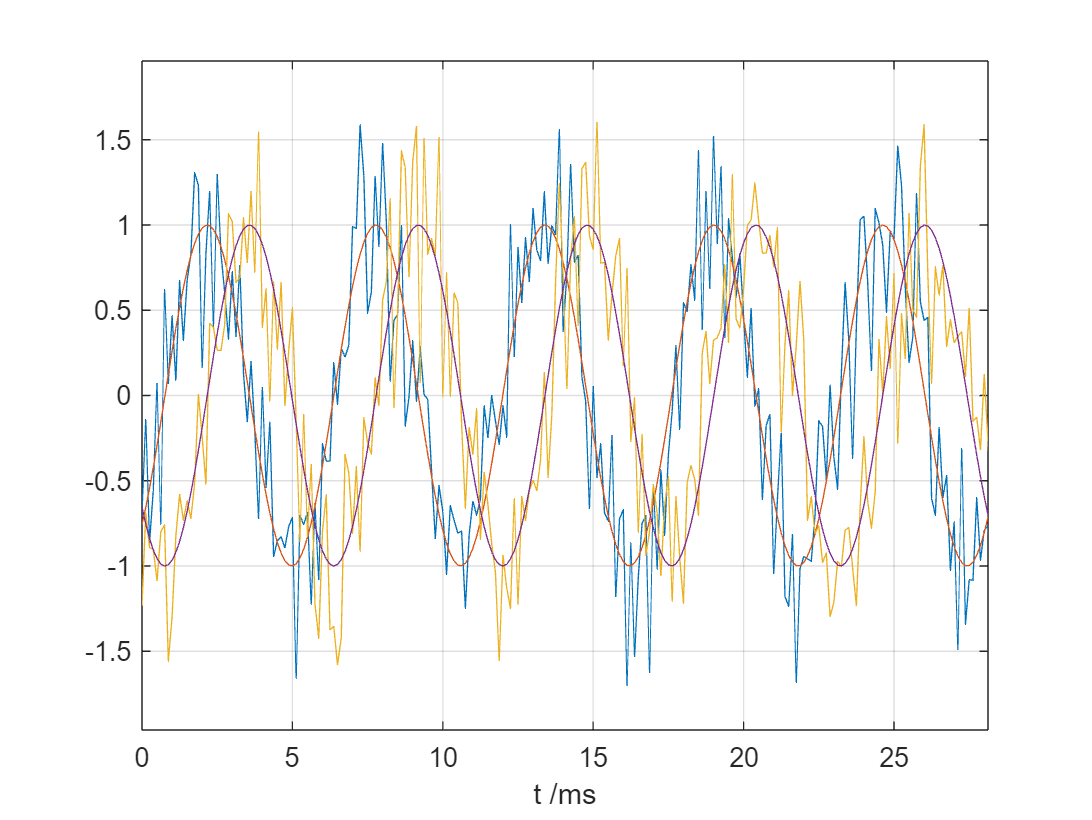

plot(t_ms,Q,t_ms,Qsig); grid
axis([0 Tdisp -maxY maxY])
grid
xlabel('t /ms');

 Calculate FFT Ampiitude Spectrum

X=fftshift(abs(fft(x)))/N;

Plot Ampitude Spectrum

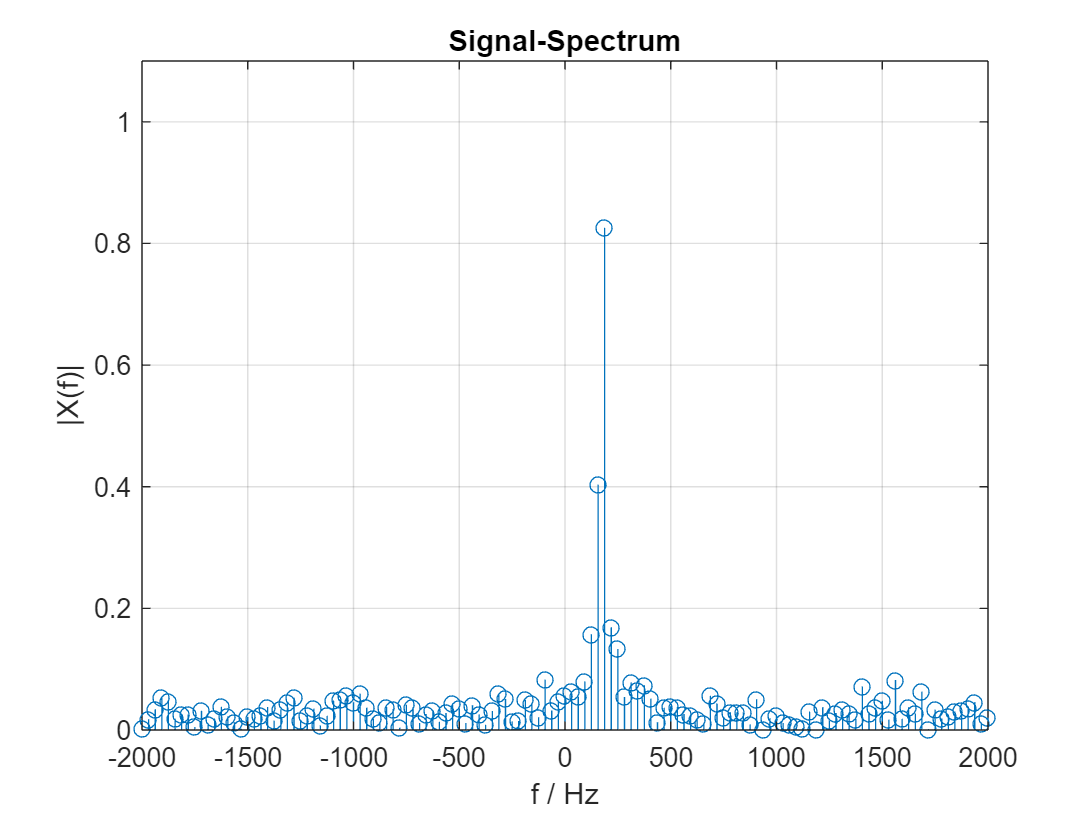

f = (-N/2:N/2-1)*fs/N; 

figure
stem(f,X);grid
%fdisp = ceil(4*fsig);
fdisp=2000;
axis([-fdisp fdisp 0 1.1]);
xlabel('f / Hz'); ylabel('|X(f)|');
title('Signal-Spectrum')

Determine Signal Frequency from Amplitude Spectrum

[Xmax, nmax] = max(X);
fsig_ =(nmax-N/2-1)*fs/N

fsig_ = 187.5000

e = fsig_-fsig                      % Error in Hertz

e = 9.3770

Interpolation Method a: Use  Higest Next Neighbour Frequency Bin

if(X(nmax+1)>X(nmax-1))     % Find n2 = index of highest neighbour bin
    n2 = nmax+1;
   else
    n2 = nmax-1;
 end
Xmax;
Xn2=X(n2);                  % Second highest neighbour        


na= (nmax+n2)/2 +((Xmax-Xn2)/(Xmax+Xn2))*(nmax-n2)/2;   % Interpolation 
fsig_a =(na-N/2-1)*fs/N                                 % Interpolated result

fsig_a = 177.2412

e_a = fsig_a - fsig                                     % Error in Hertz

e_a = -0.8818

Interpolation Method b: Use Higest Neighbour Bins from Both Sides

XR = X(nmax+1); % Neighbour bin to the right
XL = X(nmax-1); % Neighbour bin to the left 
 
nb = nmax + (XR-XL)/(XR+XL);   % Interpolate
fsig_b =(nb-N/2-1)*fs/N                                  % Interpolated result

fsig_b = 174.6904

e_b = fsig_b -fsig

e_b = -3.4326

#### FFT With Window Applied

Define a Window

%w=hamming(N);
w=kaiser(N,10);      %  Kaiser window, 2. param = beta
kw=sum(w)               % kw compensates loss of the window

kw = 99.7396

 Calculate FFT Ampiitude Spectrum on weighted input

X=fftshift(abs(fft(x.*w')))/kw;

Determine Signal Frequency from Amplitude Spectrum

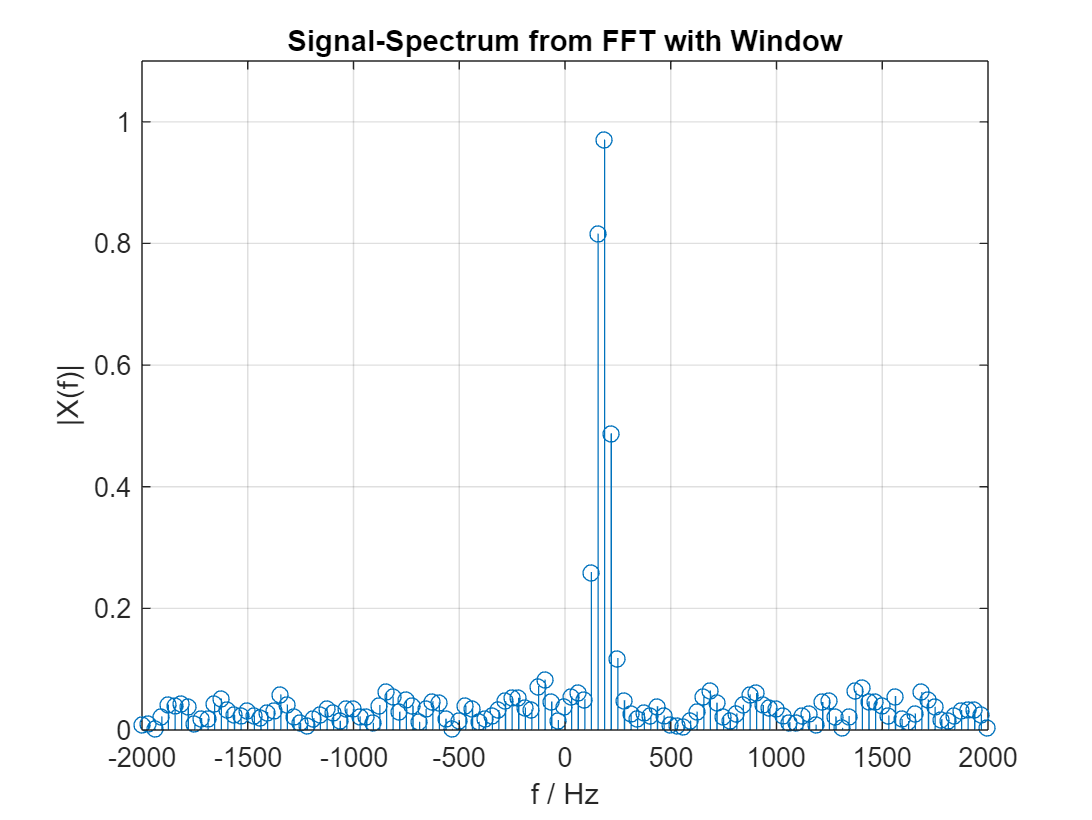

figure
stem(f,X);grid
axis([-fdisp fdisp 0 1.1]);
xlabel('f / Hz'); ylabel('|X(f)|');
title('Signal-Spectrum from FFT with Window')

Determine Signal Frequency from Amplitude Spectrum

[Xmax, nmax] = max(X);
fsigw=(nmax-N/2-1)*fs/N

fsigw = 187.5000

Interpolation Method b: Use Higest Neighbour Bins from Both Sides

XR = X(nmax+1); % Neighbour bin to the right
XL = X(nmax-1); % Neighbour bin to the left 
 
nb = nmax + (XR-XL)/(XR+XL);   % Interpolate
fsig_b =(nb-N/2-1)*fs/N                                  % Interpolated result

fsig_b = 179.6286

e_bw = fsig_b -fsig

e_bw = 1.5056

Interpolation Method c:  Find Top Position of Parabola 

Regard envelope as a parabola, defined with the top bin point and its two neighbours. Find the position of the top of the parabola:  $y=a\cdot x^2 +\textrm{bx}+c$

x=0:     $X_{\max } =c\to c=X_{\max }$           

x=1:     $X_R =a+b+c$    

x=-1:    $X_L =a-b+c$   $X_R -X_L =2b\to b=\frac{X_R -X_L }{2}$

x=1:  $X_R =a+\frac{X_R -X_L }{2}+X_{\max } \to$  $a=X_{R\;} -\frac{X_R -X_L }{2}-X_{\max } =$$\frac{X_R +X_L -2X_{\max } }{2}$

Find top of parabola: $\frac{\textrm{dy}}{\textrm{dx}}=0\to 0=\;2\textrm{ax}+b\to x_{\textrm{top}} =-\frac{b}{2a}=\;$$\frac{X_L -X_R }{X_R +X_L -2X_{\max } }$


$$x_{\textrm{top}} =\frac{2X_{\max } -X_R -X_L }{X_R -X_L }$$


dn = 0.5*(XR-XL)/(2*Xmax-XR-XL)     % deviation of top position from center bin

dn = -0.2574

df = dn * fs/N;
fsig_c = fsigw + df

fsig_c = 179.4550

e_c = fsig_c - fsig

e_c = 1.3320

**Apply Zero Padding**

Zero Padding Parameters

N2 = 2048; % New FFT length

Padded Signal

x_pad = [x  zeros(1,N2-N)];   % Fill in zeros

Calculate FFT Ampiitude Spectrum

X_pad=fftshift(abs(fft(x_pad)))/N;

Plot Ampitude Spectrum

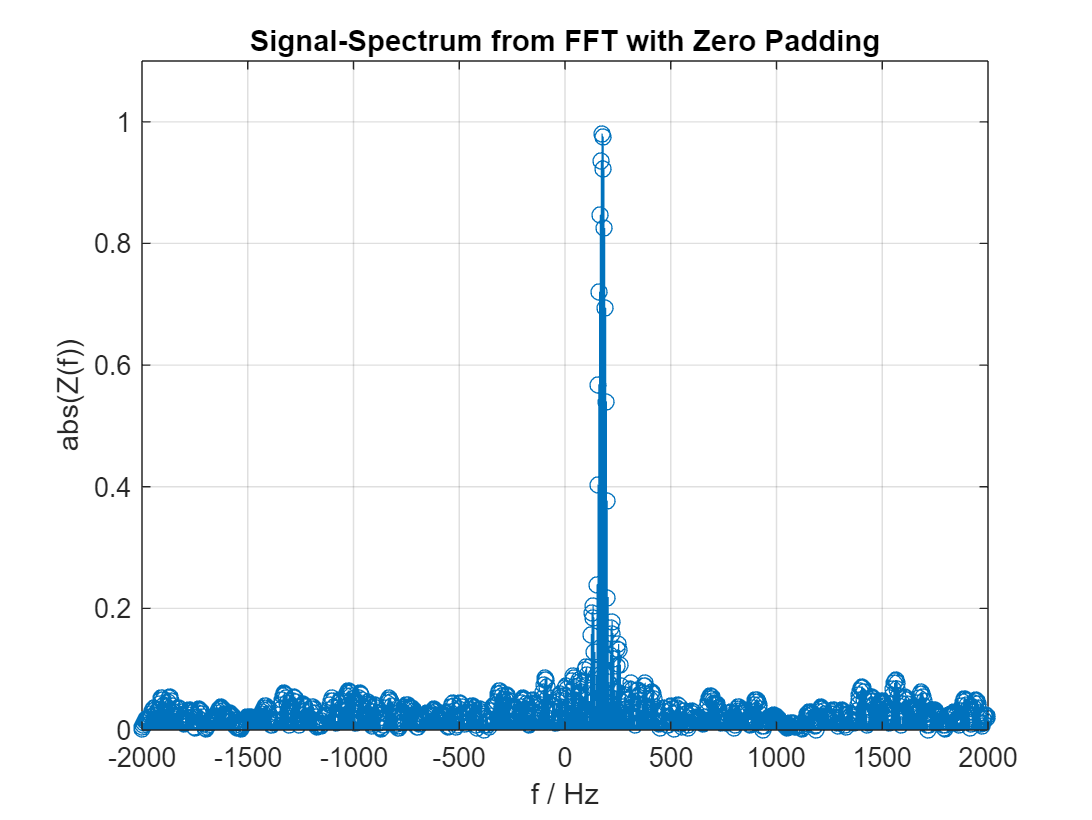

figure
f = (-N2/2:N2/2-1)*fs/N2; 
stem(f,X_pad);grid
%fdisp = ceil(4*fsig);
fdisp=2000;
axis([-fdisp fdisp 0 1.1]);
xlabel('f / Hz'); ylabel('abs(Z(f))');
title('Signal-Spectrum from FFT with Zero Padding')

Determine Signal Frequency from Amplitude Spectrum

[Xmax_pad, nmax_pad] = max(X_pad);
fsig_pad=(nmax_pad-N2/2-1)*fs/N2

fsig_pad = 175.7812

e_pad = fsig_pad - fsig                     % Error in Hertz

e_pad = -2.3417

Plot Amplitude Spectrum Around  fsig

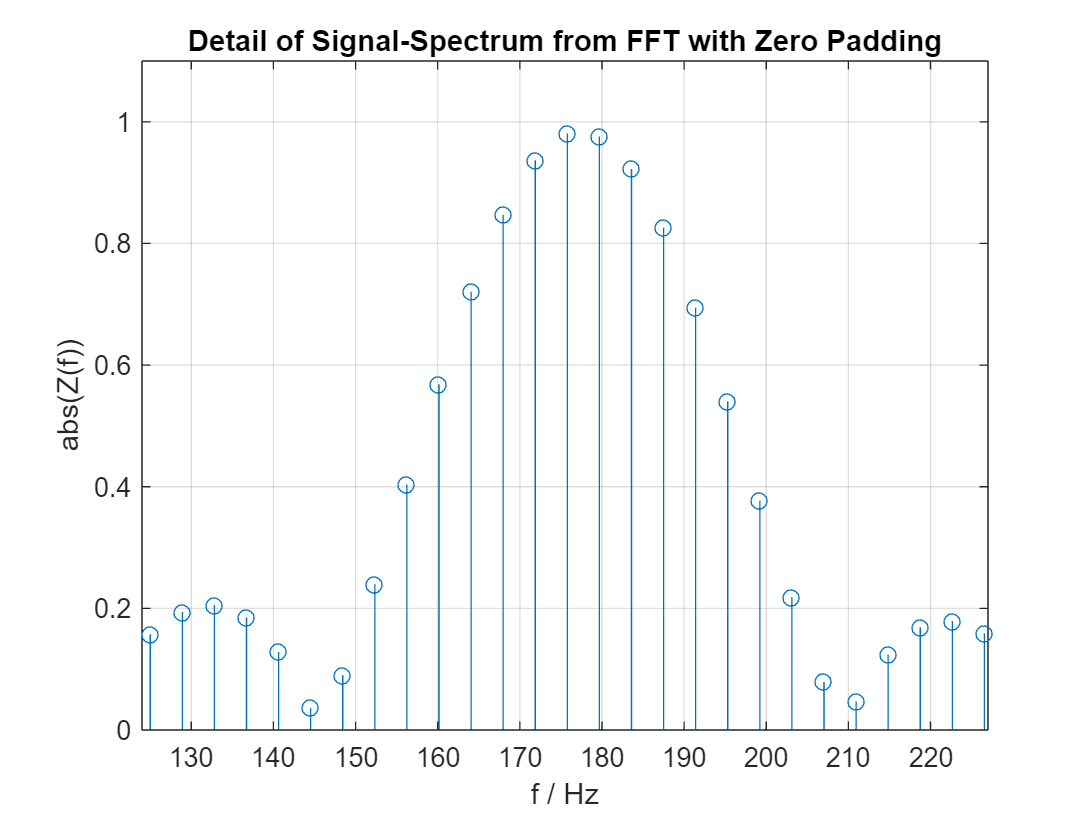

figure
stem(f,X_pad);grid
%fdisp = ceil(4*fsig);
fdisp=2000;
axis([floor(fsig_pad - N2/40)  ceil(fsig_pad + N2/40)  0 1.1]);
xlabel('f / Hz'); ylabel('abs(Z(f))');
title('Detail of Signal-Spectrum from FFT with Zero Padding')

Interpolate using Method b: Use both Neighbour Bins

XR_pad = X_pad(nmax_pad+1);
XL_pad = X_pad(nmax_pad-1);
nb_pad = nmax_pad + (XR_pad-XL_pad)/(XR_pad+XL_pad);   % Interpolate
fsigb_pad =(nb_pad-N2/2-1)*fs/N2    

fsigb_pad = 175.8614

eb_pad = fsigb_pad -fsig

eb_pad = -2.2616

Interpolate using Method c: Find Top of Parabola

Regard envelope as a parabola. Find the position of the top.

dn_pad = 0.5*(XR_pad-XL_pad)/(2*Xmax_pad-XR_pad-XL_pad)

dn_pad = 0.3999

df_pad = dn_pad * fs/N2;
fsigc_pad = fsig_pad + df_pad

fsigc_pad = 177.3434

ec_pad = fsigc_pad -fsig

ec_pad = -0.7796

Compare  Errors of Detected Frequency (in Hz)

string(fsig) +'Hz'

ans = "178.123Hz"

e       % No interpolation

e = 9.3770

e_a  % Method a

e_a = -0.8818

e_b  % Method b

e_b = -3.4326

e_c  % Method c with window

e_c = 1.3320

eb_pad  % Padding + method b

eb_pad = -2.2616

ec_pad  % Padding + method c

ec_pad = -0.7796

#### Determine the Distribution of the Frequency Detection Error

Nsim = 1000;                            % Number of simulations
errors = zeros(6, Nsim);                % Store errors from different methods

for i = 1:Nsim
    %--- generate signal for this loop   
    fsig = 40+3000*rand;                % random signal frequency
    phi  = 2*pi*rand;                   % random phse 
    Isig=cos(2*pi*fsig*t +phi);         % In-phase signal component
    Qsig=sin(2*pi*fsig*t +phi);         % Quadrature-phase signal component
    Inoise = Unoise * randn(1,N);       % In-phase noise component
    Qnoise = Unoise * randn(1,N);       % Quadrature-phase signal component
    x = Isig + Inoise +1j*(Qsig + Qnoise); 
    
    X=fftshift(abs(fft(x)))/N;

    %---- no interpolation:
    [Xmax, nmax] = max(X);
    fsig_ =(nmax-N/2-1)*fs/N;
    errors(1,i) = fsig_-fsig;  

    %---- method a interpolate with highest next neigbour
    if(X(nmax+1)>X(nmax-1))     % Find n2 = index of second highest neighbour bin
        n2 = nmax+1;
    else
        n2 = nmax-1;
    end
    Xn2=X(n2);                                              % highest neighbour amplitude       
    na= (nmax+n2)/2 +((Xmax-Xn2)/(Xmax+Xn2))*(nmax-n2)/2;   % Interpolation 
    fsig_a =(na-N/2-1)*fs/N ;                               % Interpolated result
    errors(2,i) = fsig_a - fsig;    

    %---- method b inperpolate wiht next neighbours on both sides
    XR = X(nmax+1); % Neighbour bin to the right
    XL = X(nmax-1); % Neighbour bin to the left 
     
    nb = nmax + (XR-XL)/(XR+XL);   % Interpolate
    fsig_b =(nb-N/2-1)*fs/N;                                 % Interpolate
    errors(3,i) = fsig_b - fsig;    

    %---- zero padding  
    x_pad = [x  zeros(1,N2-N)];   % Fill in zeros
    X_pad=fftshift(abs(fft(x_pad)))/N;
    [Xmax_pad, nmax_pad] = max(X_pad);
    fsig_pad=(nmax_pad-N2/2-1)*fs/N2;
    errors(4,i) = fsig_pad -fsig;                           % no interpolation

    %----interpolate with method b, using next neighbours on both sides
    XR_pad = X_pad(nmax_pad+1);
    XL_pad = X_pad(nmax_pad-1);

    nb_pad = nmax_pad + (XR_pad-XL_pad)/(XR_pad+XL_pad);   % Interpolate
    fsigb_pad =(nb_pad-N2/2-1)*fs/N2;    
    errors(5,i) = fsigb_pad -fsig;

%----    interpolate with method c, find top position of parabola
    dn_pad = 0.5*(XR_pad-XL_pad)/(2*Xmax_pad-XR_pad-XL_pad);
    df_pad = dn_pad * fs/N2;
    errors(6,i) = fsig_pad + df_pad-fsig;
end


Show Error Distributions 

(see locaf function definition below)

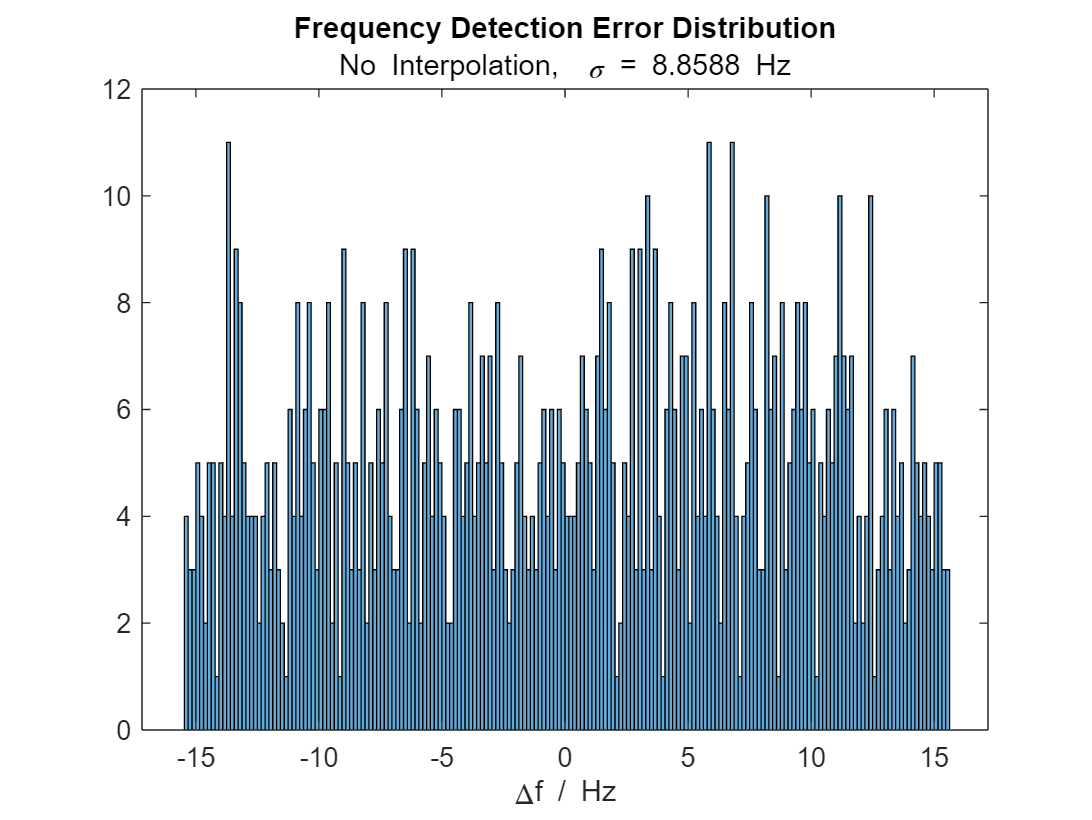

errorhist(1,errors,fs, N, 'No Interpolation');

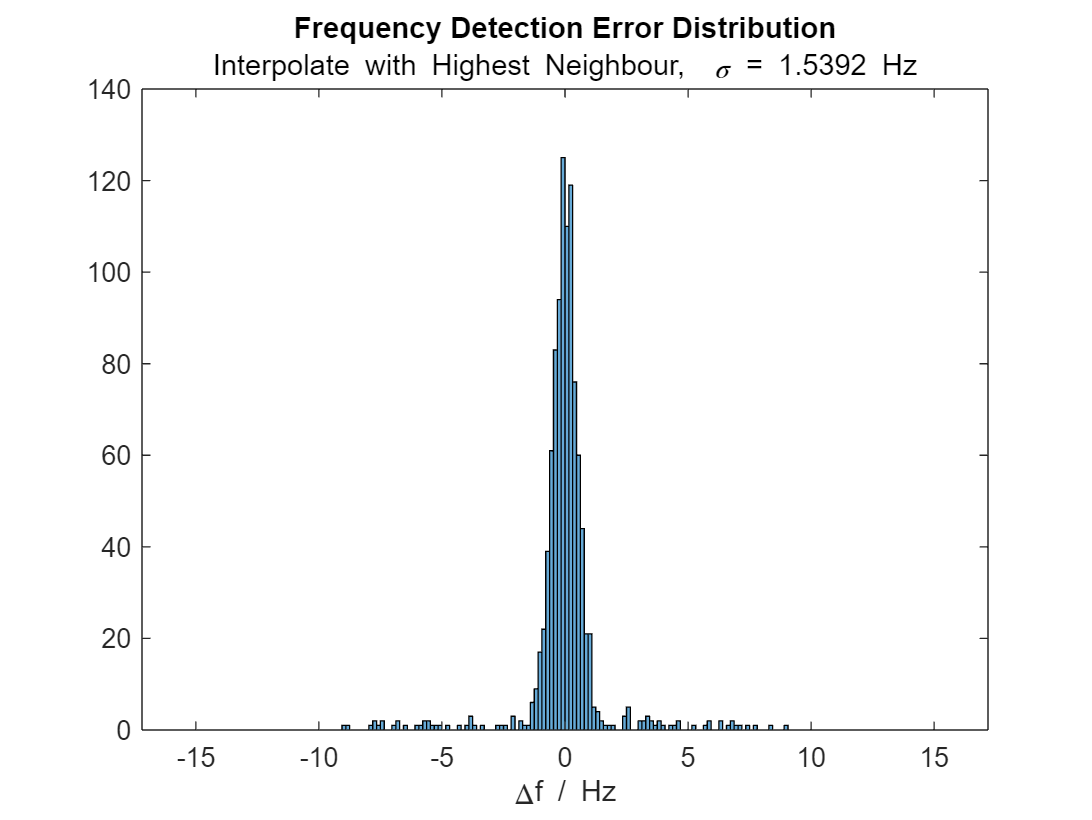

errorhist(2,errors,fs, N, 'Interpolate with Highest Neighbour');

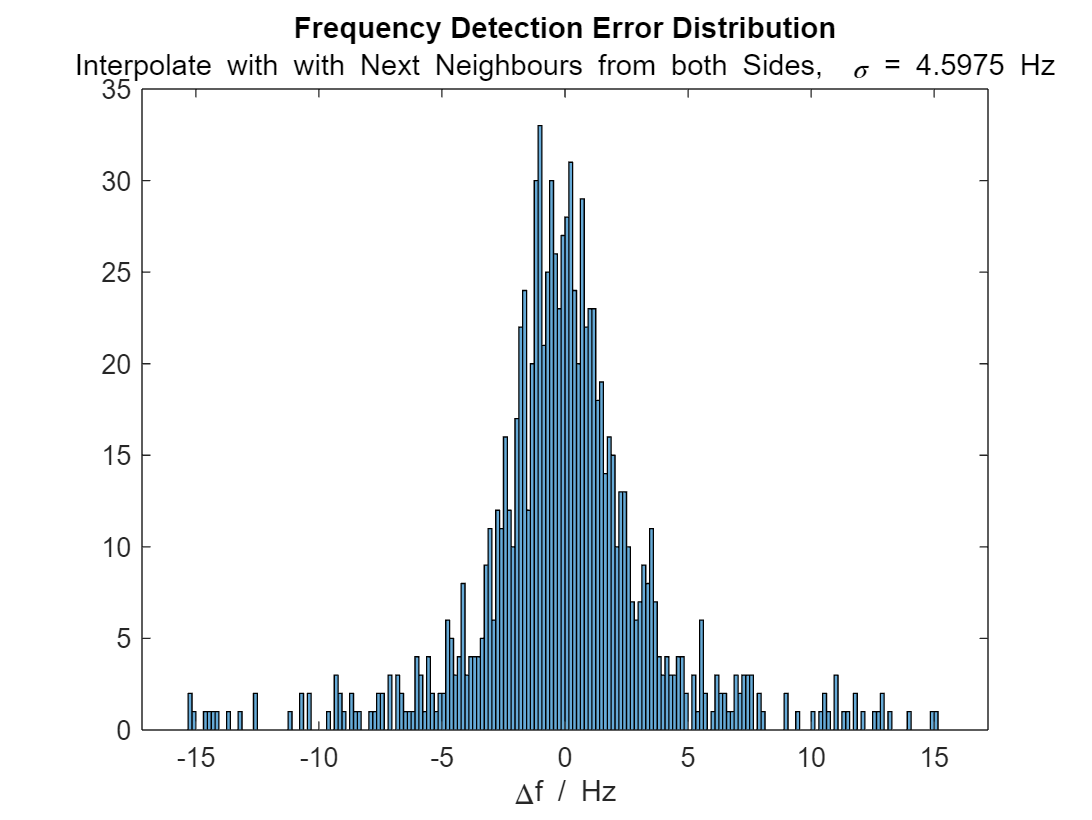

errorhist(3,errors,fs, N, 'Interpolate with with Next Neighbours from both Sides');

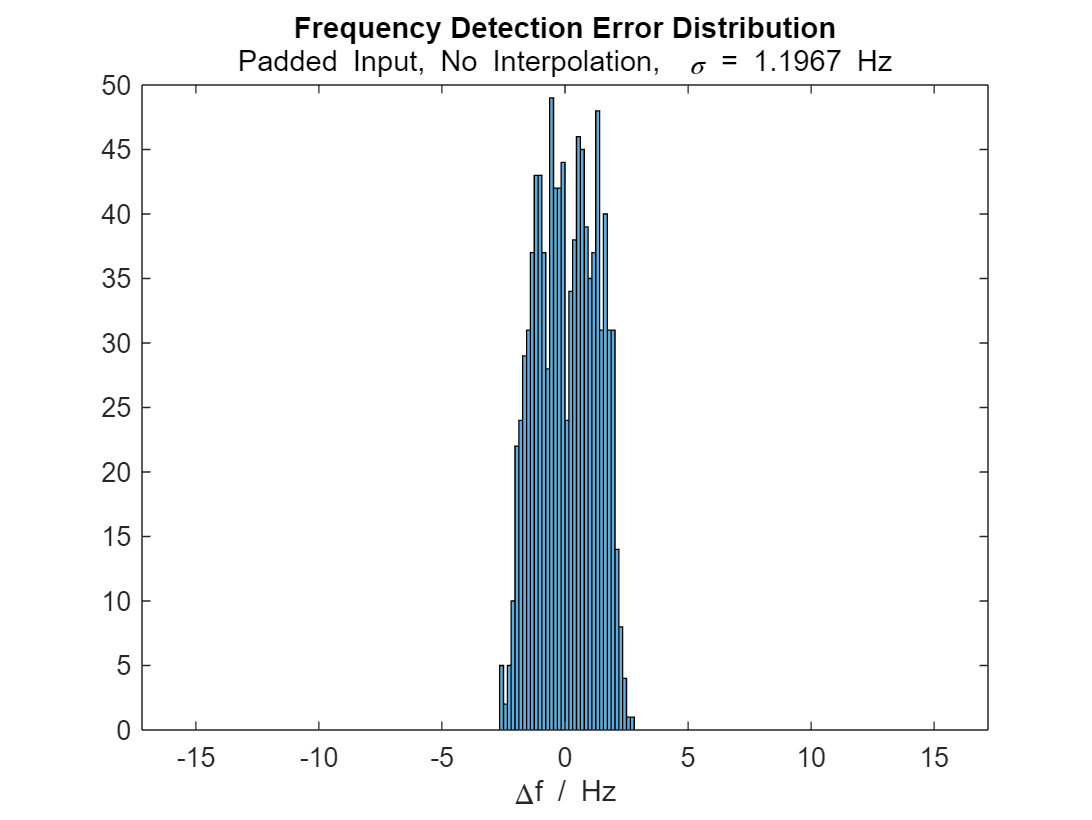

errorhist(4,errors,fs, N, 'Padded Input, No Interpolation');

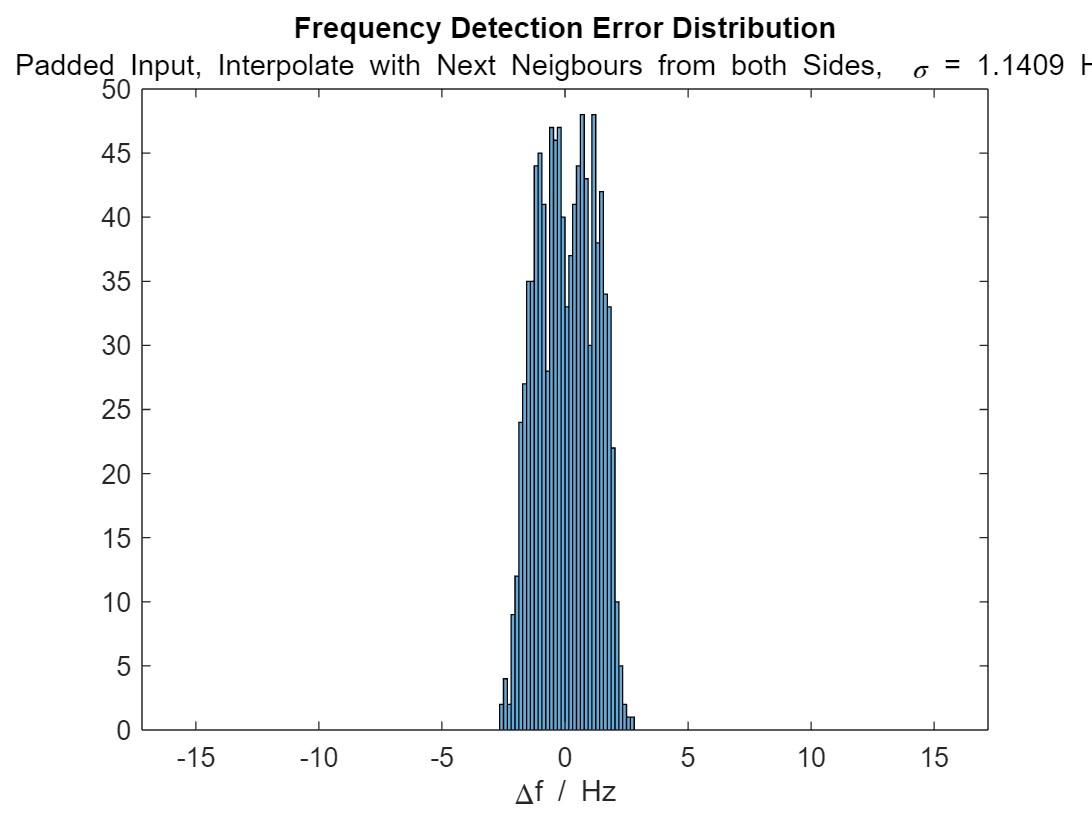

errorhist(5,errors,fs, N, 'Padded Input, Interpolate with Next Neigbours from both Sides');

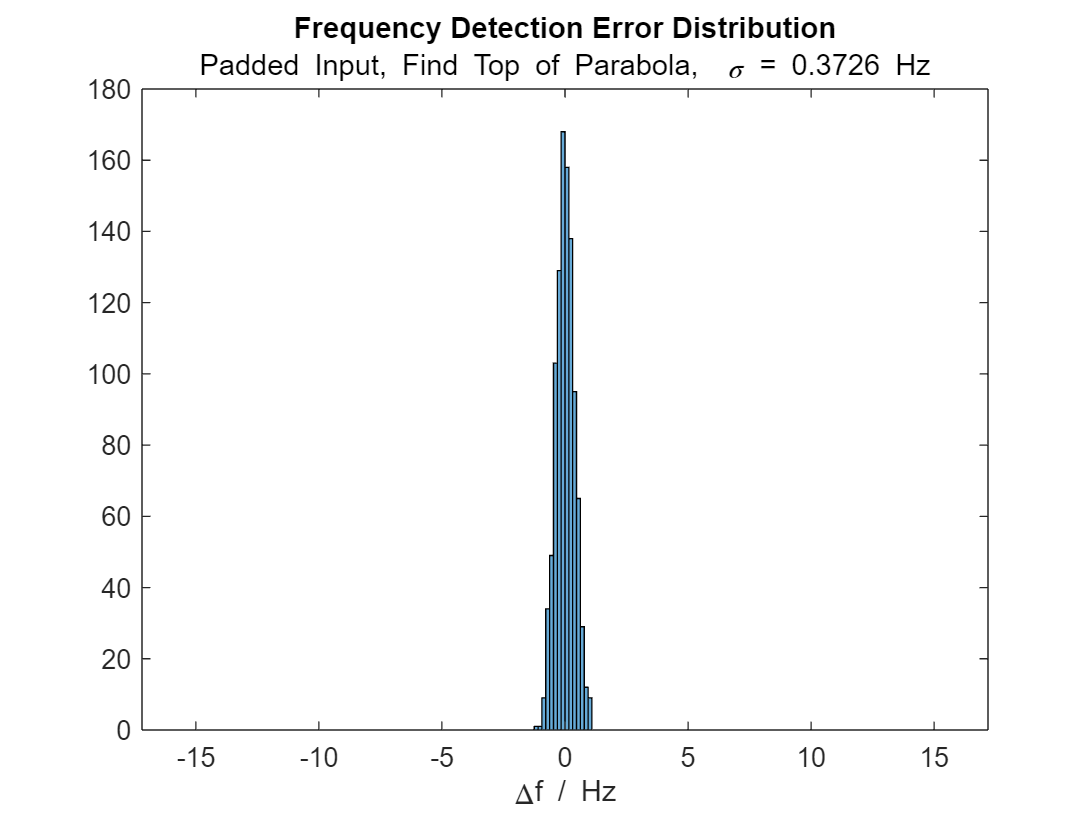

errorhist(6,errors,fs, N, 'Padded Input, Find Top of Parabola');

**Local Functions**

function h = errorhist( n, err, fs, N,txt)
    Nhist=200;                      %Number of bins 
    step = fs/(Nhist*N);            
    edges=-fs/(2*N) : step : fs/(2*N);
    h=histogram(err(n,:),edges);
    sigma=std(err(n,:));
    txt = string(txt) + ',  \sigma = ' + string(sigma) + ' Hz';
    title('Frequency Detection Error Distribution', txt  );
    xlabel('\Deltaf / Hz')
end